clear variables; close all; clc

s = tf('s');
G = 8/((s+1)*(s+2))


G =
 
        8
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



H = 1/(s+3)


H =
 
    1
  -----
  s + 3
 
Continuous-time transfer function.



C = 0.987/(1+0.267*s)^2


C =
 
            0.987
  -------------------------
  0.07129 s^2 + 0.534 s + 1
 
Continuous-time transfer function.



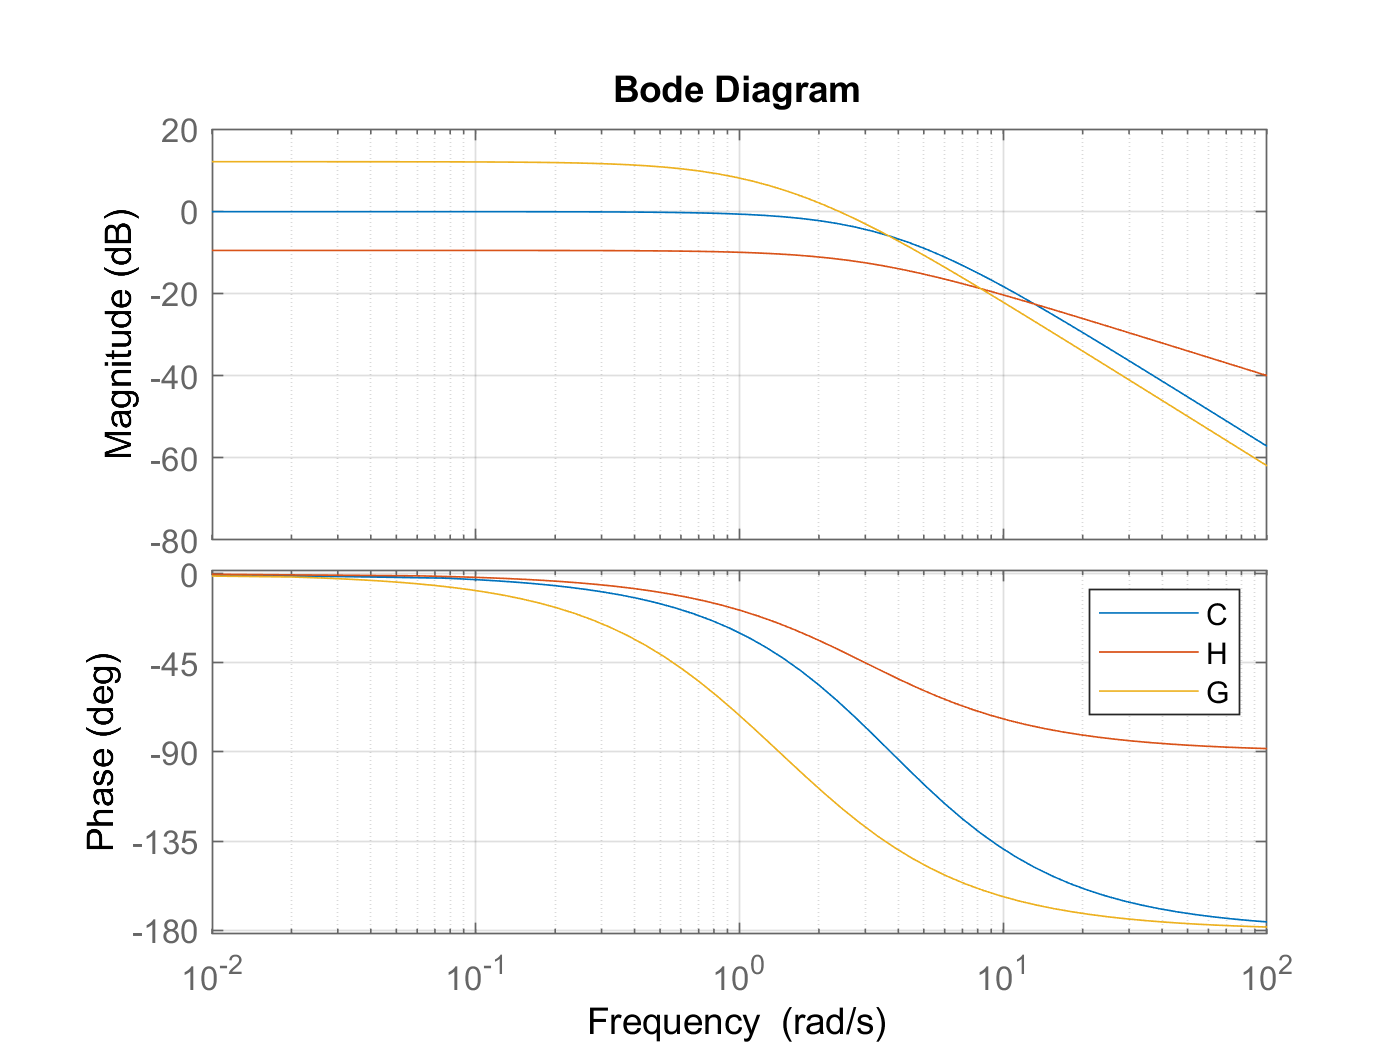

figure; hold on; bode(C); bode(H); bode(G); grid on; legend;

S = minreal(H + C*G)


S =
 
        s^4 + 10.49 s^3 + 38.5 s^2 + 167.8 s + 360.3
  ---------------------------------------------------------
  s^5 + 13.49 s^4 + 69.97 s^3 + 172.6 s^2 + 199.2 s + 84.16
 
Continuous-time transfer function.



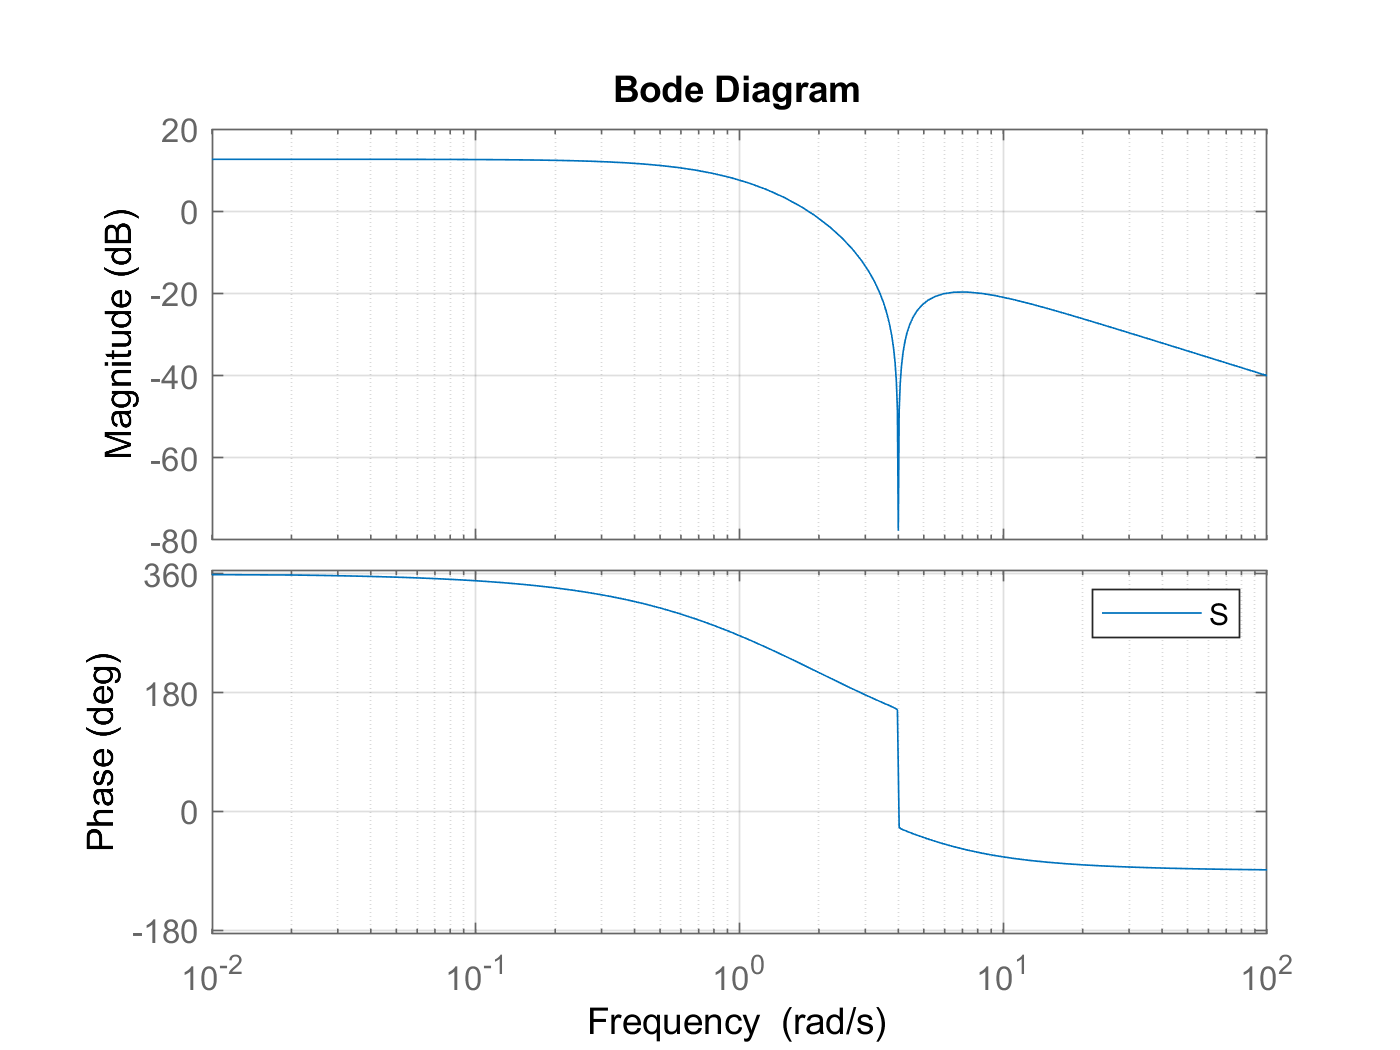

figure; hold on; bode(S); grid on; legend;

omega = 4;
fr = freqresp(S, omega)

fr = 7.1586e-05 + 1.0966e-04i

mag2db(abs(fr))

ans = -77.6576